# Modelo

1. Definir ecuaciones para el modelo y cargar los datos de la serie de tiempo

syms  Ms(t) Me(t) Mi(t) Hs(t) He(t) Hi(t) Hr(t) Hit(t)

syms lambda beta_m mu_m theta_m mu_h beta_h theta_h...
    gamma_h


H=Hs+He+Hi+Hr;
M=Ms+Me+Mi;
ode1 = diff(Ms) == lambda - beta_m*Hi*Ms/H - (mu_m)*Ms;
ode2 = diff(Me) == beta_m*Hi*Ms/H - (theta_m+mu_m)*Me;
ode3 = diff(Mi) == theta_m*Me - mu_m*Mi;
ode4 = diff(Hs) == -beta_h*Mi*Hs/M + (He+Hi+Hr)*mu_h;
ode5 = diff(He) == beta_h*Mi*Hs/M - (theta_h+mu_h)*He;
ode6 = diff(Hi) == theta_h*He - (gamma_h+mu_h)*Hi;
ode7 = diff(Hr) == gamma_h*Hi - mu_h*Hr;
ode8 = diff(Hit) == theta_h*He;
odes=[ode1; ode2 ;ode3; ode4; ode5 ;ode6; ode7; ode8];
vars=[Hit Hi Me Hr Hs He Ms Mi];
opts = odeset('NonNegative',1:8);


2. Preparar los datos:

Escogimos la ventana de tiempo (entre la semana 153 y la semana 233).


load Range7.mat
[T,~]=gsua_dpmat(odes,vars,[0 150],'7m','output',1,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

load('DataBello_full.mat');
ydata=DataBello.cases(153:233)';
xdata=linspace(0,length(ydata)-1,length(ydata));
ydata2=ydata;
for i=1:length(ydata)
ydata2(i)=sum(ydata(1:i));
end

3.

3.1. Preparamos los datos: usamos la tabla con los rangos y los valores nominales de los parametros y 

preparamos la matriz de diseño experimental.

[T,~]=gsua_dpmat(odes,vars,[0 80],'7m','output',1,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T.Properties.CustomProperties.output = 1;
M = gsua_dmatrix(T,100);
T

T = 13×2 table
                        Range              Nominal  
               _______________________    __________

    Me0                0           100            50
    Hr0            81405    1.5881e+05    1.2011e+05
    Hs0        2.444e+05    3.2173e+05    2.8307e+05
    He0               18            72            45
    Ms0                0       1.2e+06         6e+05
    Mi0                0           100            50
    beta_h             0             4             2
    beta_m             0             4             2
    gamma_h          0.5          1.75         1.125
    lambda          1881         42694         22288
    mu_m            0.16           0.2          0.18
    theta_h          0.

3.2. Análisis de sensibilidad

Usamos el toolbox para realizar el análisis de sensibilidad variando los parámetros según los rangos que 

nos dieron.

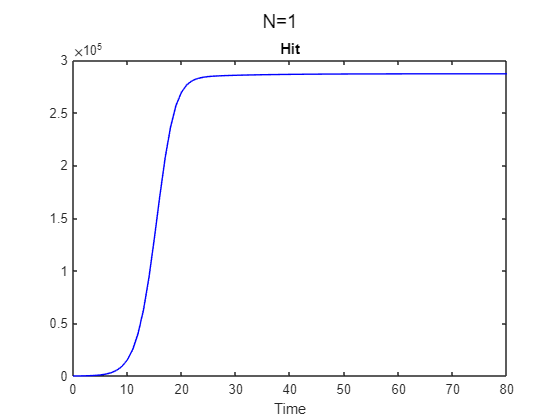


ynom = gsua_eval(T.Nominal,T);

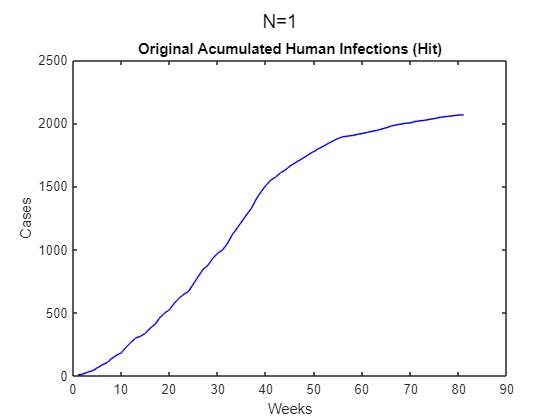


plot(cumsum(ydata),'b')
title('Original Acumulated Human Infections (Hit)')
xlabel('Weeks')
ylabel('Cases')

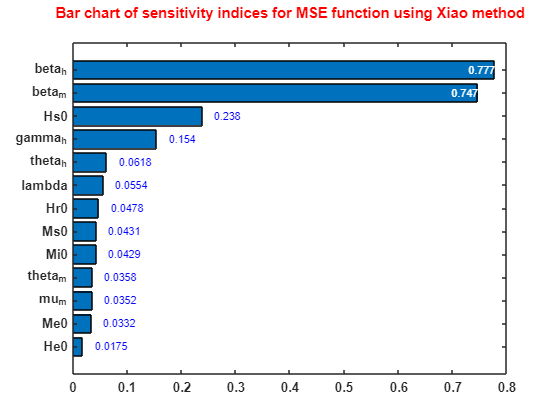

%savefig('iteration1/figures/NominalValues.fig')

clf
Tsa = gsua_sa(M,T,'parallel', false, 'SensMethod', 'Xiao', 'ynom', ynom);
gsua_plot('Bar',Tsa,Tsa.STi)

%%savefig('iteration1/figures/SensibilityAnalisis.fig')


3.3. Confiabilidad

Mientras mayor sea c, mayor confianza tenemos en los resultados del análisis.


c = sum(Tsa.Si)/sum(abs(Tsa.Si))

c = 0.9637

3.4 Fijar parámetros

Según el análisis previo,el ultimo parámetro es insensibles, entonces lo podemos fijar ya que no es identificable.

Este parámetros es He0

Para esto usamos los valores nominales de la tabla T.

vars=[Hit Hi He Me Hr Hs Ms Mi];

HeO = T.Nominal('He0');

NewRange = Range;
NewRange(3,:) = HeO; 
NewRange(4:6,:) = [Range(3,:); Range(4,:); Range(5,:)];

[T,~]=gsua_dpmat(odes,vars,[0 80],'7m','output',1,'opt',opts,'Range',NewRange);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T.Properties.CustomProperties.output = 1;
M = gsua_dmatrix(T,100);
T

T = 12×2 table
                        Range              Nominal  
               _______________________    __________

    Me0                0           100            50
    Hr0            81405    1.5881e+05    1.2011e+05
    Hs0        2.444e+05    3.2173e+05    2.8307e+05
    Ms0                0       1.2e+06         6e+05
    Mi0                0           100            50
    beta_h             0             4             2
    beta_m             0             4             2
    gamma_h          0.5          1.75         1.125
    lambda          1881         42694         22288
    mu_m            0.16           0.2          0.18
    theta_h          0.7          1.75         1.225
    theta_m         0.5

4. Estimación de parámetros.


opt = optimoptions('lsqcurvefit','UseParallel',true,'Display','iter');
[T7,res] = gsua_pe(T,xdata,ydata2,'N',300,'opt',opt); %mover N ( 100 buena, 50 aceptable, 10 :( )
%save('iteration1/values/Results7.mat','T7','res','xdata','ydata2')

5. Análisis de identificabilidad

Escogemos las curvas que estén más cercanas a la mejor.

th = sum(res<res(1)*1.01)

th = 22

Sim300 Done
Sim299 Done
Sim298 Done
Sim297 Done
Sim296 Done
Sim295 Done
Sim294 Done
Sim293 Done
Sim292 Done
Sim291 Done
Sim290 Done
Sim289 Done
Sim288 Done
Sim287 Done
Sim286 Done
Sim285 Done
Sim284 Done
Sim283 Done
Sim282 Done
Sim281 Done
Sim280 Done
Sim279 Done
Sim278 Done
Sim277 Done
Sim276 Done
Sim275 Done
Sim274 Done
Sim273 Done
Sim272 Done
Sim271 Done
Sim270 Done
Sim269 Done
Sim268 Done
Sim267 Done
Sim266 Done
Sim265 Done
Sim264 Done
Sim263 Done
Sim262 Done
Sim261 Done
Sim260 Done
Sim259 Done
Sim258 Done
Sim257 Done
Sim256 Done
Sim255 Done
Sim254 Done
Sim253 Done
Sim252 Done
Sim251 Done
Sim250 Done
Sim249 Done
Sim248 Done
Sim247 Done
Sim246 Done
Sim245 Done
Sim244 Done
Sim243 Done
Sim242 Done
Sim241 Done
Sim240 Done
Sim239 Done
Sim238 Done
Sim237 Done
Sim236 Done
Sim235 Done
Sim234 Done
Sim233 Done
Sim232 Done
Sim231 Done
Sim230 Done
Sim229 Done
Sim228 Done
Sim227 Done
Sim226 Done
Sim225 Done
Sim224 Done
Sim223 Done
Sim222 Done
Sim221 Done
Sim220 Done
Sim219 Done
Sim218 Done
Sim2

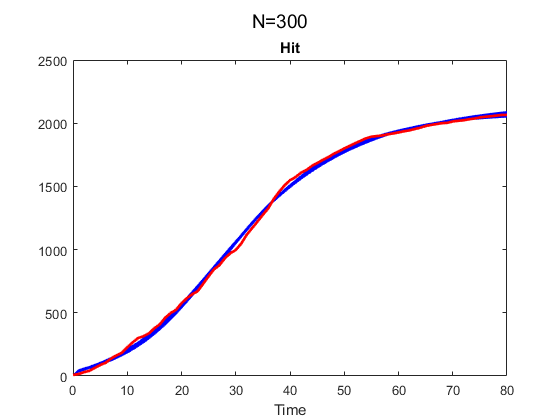

y7 = gsua_eval(T7.Estlsqc(:,1:end),T7,xdata,ydata2);

%savefig('iteration1/figures/curves.fig')

Comparamos la mejor curva con los valores reales para ver que tan bien ajusta.

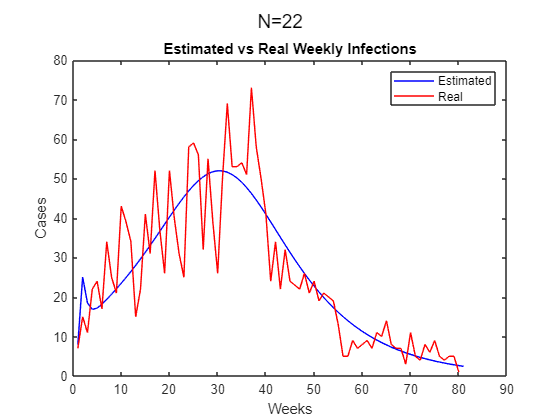

bestest = y7(1,:);
trend = [bestest(1),bestest(2:end)-bestest(1:end-1)];
plot(trend,'b')
hold on
plot(diff(ydata2),'r')
title('Estimated vs Real Weekly Infections')
xlabel('Weeks')
ylabel('Cases')
legend({'Estimated','Real'})

%savefig('iteration1/figures/EstimatedvsReal.fig')

Ahora visualizamos el análisis de identificabilidad para asegurarnos de la fiabilidad del modelo ajustado.

T7.Nominal = T7.Estlsqc(:,1);
%res : funciones de costo
th = sum(res<res(1)*1.01) 

th = 22

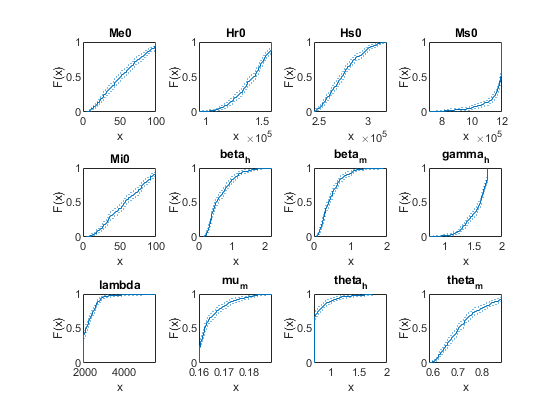

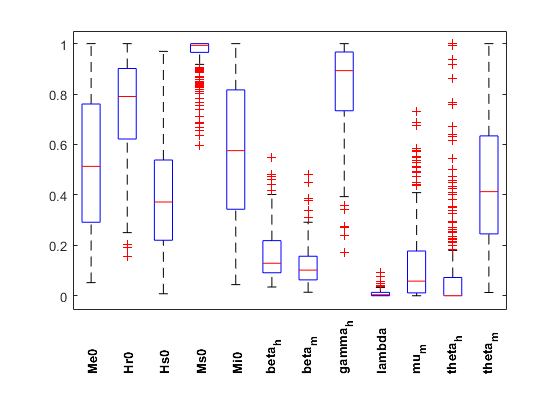

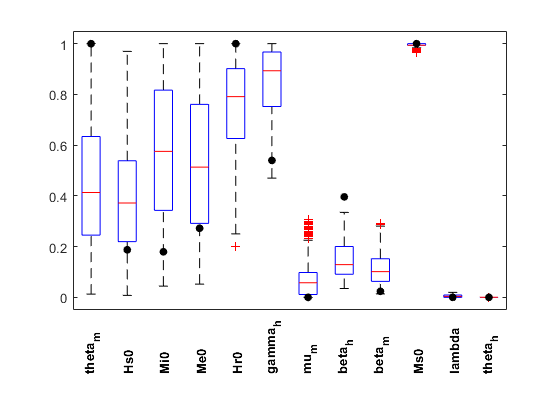

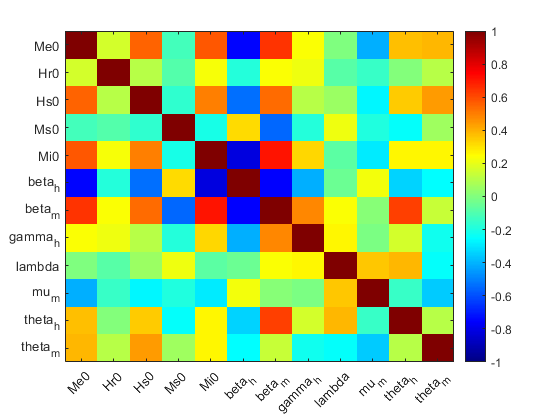

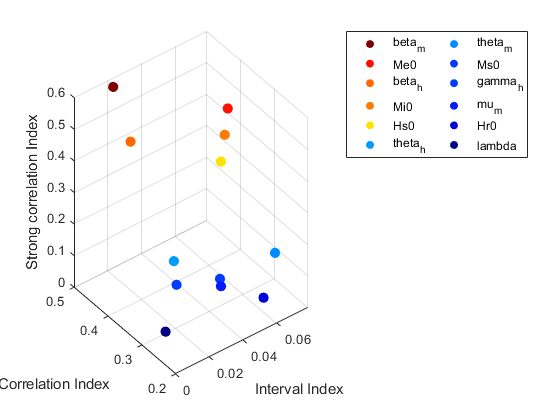

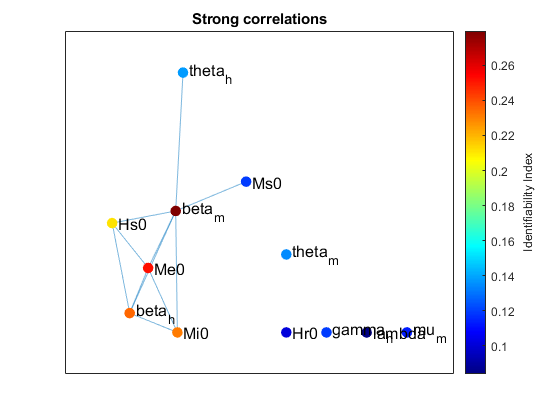

T = 12×6 table
                        Range               Nominal        Estlsqc           Est          index                           Ranges                     
                                                                                                                         Range              Nominal  
               ________________________    __________    ____________    ____________    ________    ________________________________________________

    Me0            47.447        55.229        51.338    1×300 double    1×300 double      0.2516    Me0                0           100            50
    Hr0        1.4048e+05     1.447e+05    1.4259e+05    1×300 double    1×300 double     0.101


T7ia = gsua_ia(T7,T7.Estlsqc(:,1:end), false, true); 

%savefig('iteration1/figures/CorrelationsDiag.fig')

6. Análisis de incertidumbre

Veamos que las curvas hagan una banda al lado de los datos que estamos estimando. Si la banda es chevere,

(visualmente) terminamos, si no, debemos ffijar algún parámetro. 

Progress: 100%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 12:50:10
Number of simulations: 100


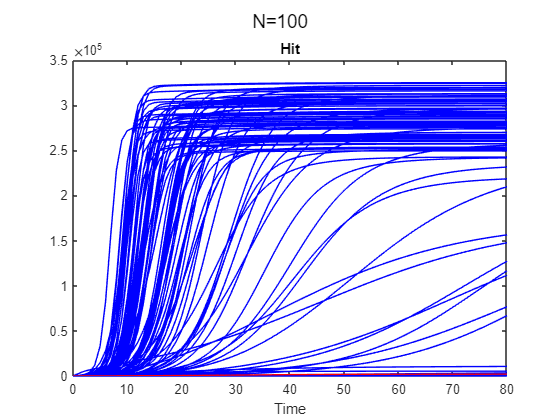

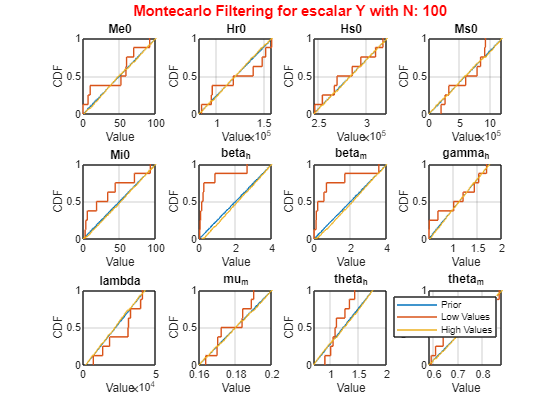


Ua = gsua_ua(M, T7, 'parallel', false, 'ynom',ydata2);

%savefig('iteration1/figures/Montecarlo.fig')

## Segunda iteracion de los calculos

Debemos de repetir todo desde el paso 3 (el análisis de sensibilidad) pero habiendo aumentado los rangos de las

variables que se observan desde el boxplot de identificabilidad.

Aumentamos los rangos de theta_h, theta_m, lambda, mu_m, Ms0 .

T.Range('theta_h',1) = 0.5;
T.Range('lambda',1) = 1500;
T.Range('mu_m',1) = 0.12;
T.Range('beta_m',1) = 0;
T.Range('Ms0',2) = 1.5e6;
T.Range('theta_m',2) = 1.2;
T.Range('Hr0',2) = 2e5;
%save('iteration1/values/T.mat','T')

4. Estimación de parámetros

opt = optimoptions('lsqcurvefit','UseParallel',true,'Display','iter');
[T7_1,res_1] = gsua_pe(T,xdata,ydata2,'N',300,'opt',opt); 
%save('iteration2/values/Results7.mat','T7_1','res_1','xdata','ydata2')

5. Análisis de identificabilidad

th_1 = sum(res<res(1)*1.8)

th_1 = 279

Sim279 Done
Sim278 Done
Sim277 Done
Sim276 Done
Sim275 Done
Sim274 Done
Sim273 Done
Sim272 Done
Sim271 Done
Sim270 Done
Sim269 Done
Sim268 Done
Sim267 Done
Sim266 Done
Sim265 Done
Sim264 Done
Sim263 Done
Sim262 Done
Sim261 Done
Sim260 Done
Sim259 Done
Sim258 Done
Sim257 Done
Sim256 Done
Sim255 Done
Sim254 Done
Sim253 Done
Sim252 Done
Sim251 Done
Sim250 Done
Sim249 Done
Sim248 Done
Sim247 Done
Sim246 Done
Sim245 Done
Sim244 Done
Sim243 Done
Sim242 Done
Sim241 Done
Sim240 Done
Sim239 Done
Sim238 Done
Sim237 Done
Sim236 Done
Sim235 Done
Sim234 Done
Sim233 Done
Sim232 Done
Sim231 Done
Sim230 Done
Sim229 Done
Sim228 Done
Sim227 Done
Sim226 Done
Sim225 Done
Sim224 Done
Sim223 Done
Sim222 Done
Sim221 Done
Sim220 Done
Sim219 Done
Sim218 Done
Sim217 Done
Sim216 Done
Sim215 Done
Sim214 Done
Sim213 Done
Sim212 Done
Sim211 Done
Sim210 Done
Sim209 Done
Sim208 Done
Sim207 Done
Sim206 Done
Sim205 Done
Sim204 Done
Sim203 Done
Sim202 Done
Sim201 Done
Sim200 Done
Sim199 Done
Sim198 Done
Sim197 Done
Sim1

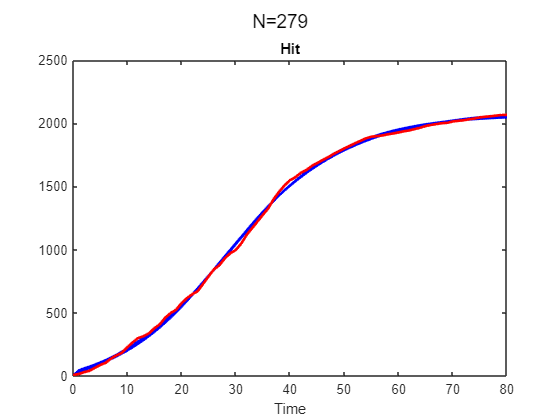

y7_1 = gsua_eval(T7.Estlsqc(:,1:th_1),T7,xdata,ydata2);

%savefig('iteration2/figures/curves.fig')

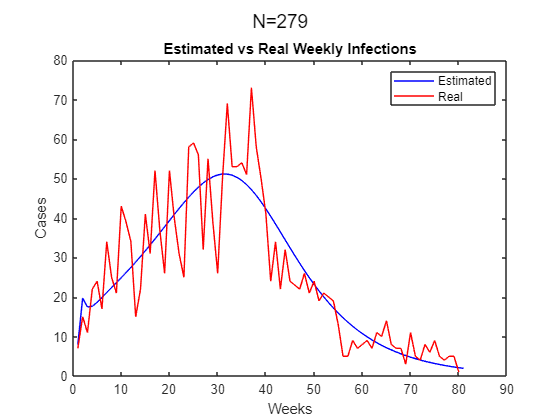

bestest_1 = y7_1(1,:);
trend = [bestest_1(1),bestest_1(2:end)-bestest_1(1:end-1)];
plot(trend,'b')
hold on
plot(diff(ydata2),'r')
title('Estimated vs Real Weekly Infections')
xlabel('Weeks')
ylabel('Cases')
legend({'Estimated','Real'})

%savefig('iteration2/figures1/EstimatedvsReal.fig')

T7.Nominal = T7.Estlsqc(:,1);
%res : funciones de costo
th_1 = sum(res<res(1)*1.8) % threshold, cambiar el 1.01

th_1 = 279

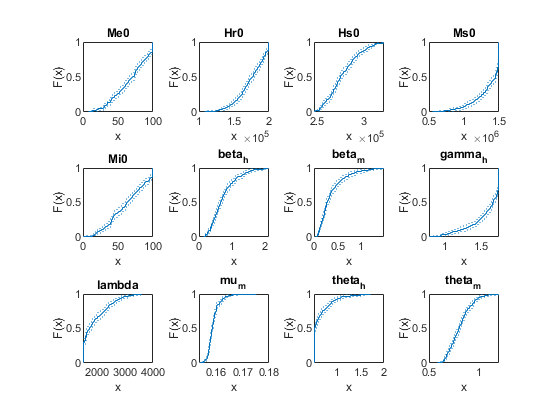

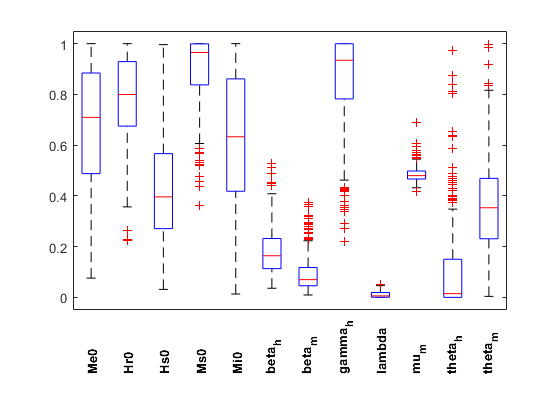

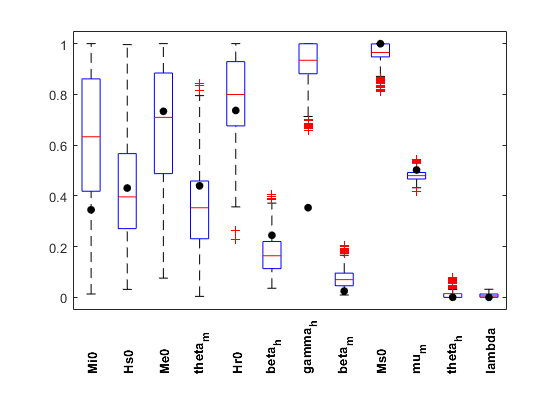

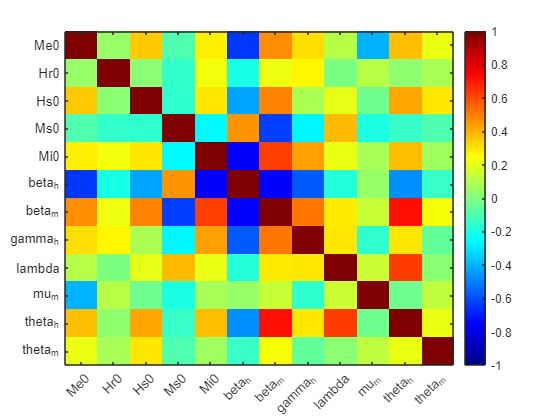

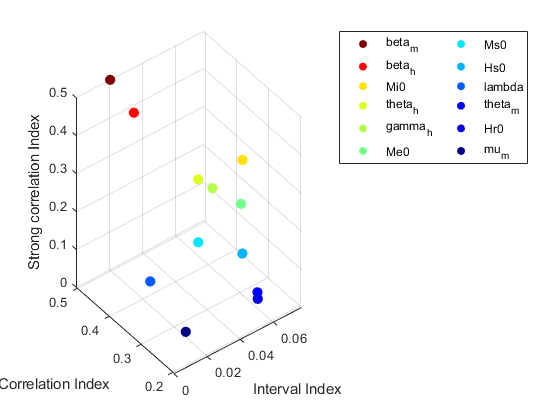

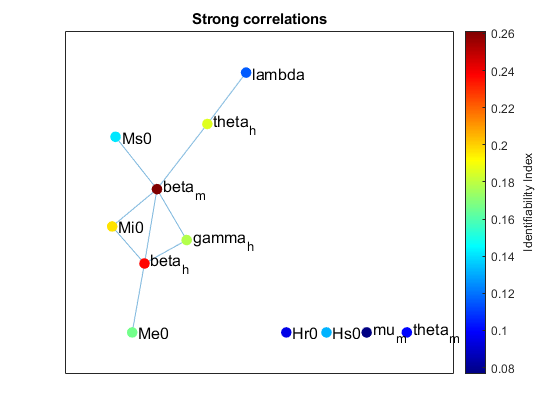

T = 12×5 table
                        Range               Nominal        Estlsqc           Est          index  
               ________________________    __________    ____________    ____________    ________

    Me0            67.401        74.535        70.968    1×300 double    1×279 double     0.16644
    Hr0        1.7326e+05    1.7925e+05    1.7626e+05    1×300 double    1×279 double    0.094769
    Hs0        2.7255e+05    2.7751e+05    2.7503e+05    1×300 double    1×279 double     0.13147
    Ms0        1.4188e+06    1.4767e+06    1.4478e+06    1×300 double    1×279 double       0.141
    Mi0            59.455        67.173        63.314    1×300 double    1×279 double     0.19667
    beta_h         0.5981 

%th = 476 %el parametro que habia dado el profe, a nosotros nos da 1????

T7ia = gsua_ia(T7,T7.Estlsqc(:,1:th_1), false, true); 

%savefig('iteration2/figures/Correlations.fig')

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 22:32:17
Number of simulations: 100


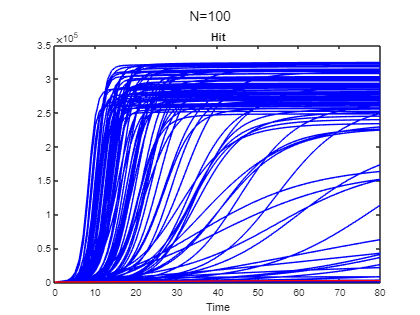

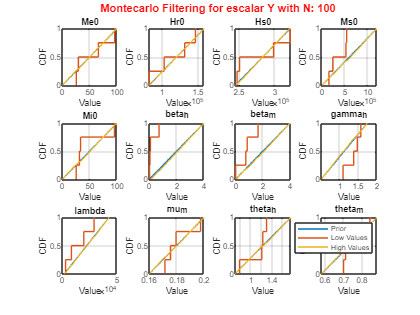

gsua_ua(M, T7, 'parallel', false, 'ynom',ydata2);

## Tercera Iteracion

Fijamos beta_m

NewRange(10,:) = 0.0993;

[T,~]=gsua_dpmat(odes,vars,[0 80],'7m','output',1,'opt',opts,'Range',NewRange);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T.Properties.CustomProperties.output = 1;
M = gsua_dmatrix(T,100);
T

T = 11×2 table
                        Range              Nominal  
               _______________________    __________

    Me0                0           100            50
    Hr0            81405    1.5881e+05    1.2011e+05
    Hs0        2.444e+05    3.2173e+05    2.8307e+05
    Ms0                0       1.2e+06         6e+05
    Mi0                0           100            50
    beta_h             0             4             2
    gamma_h          0.5          1.75         1.125
    lambda          1881         42694         22288
    mu_m            0.16           0.2          0.18
    theta_h          0.7          1.75         1.225
    theta_m         0.58          0.88          0.73


4. Estimamos los parámetros

opt = optimoptions('lsqcurvefit','UseParallel',true,'Display','iter');
[T7,res] = gsua_pe(T,xdata,ydata2,'N',300,'opt',opt); 

Generating a valid matrix for estimations
Estimation 1
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


%save('iteration3/values/Results7.mat','T7_2','res_2','xdata','ydata2')

5. Análisis de identificabilidad

th_2 = sum(res<res(1)*1.03)

th_2 = 65

Sim300 Done
Sim299 Done
Sim298 Done
Sim297 Done
Sim296 Done
Sim295 Done
Sim294 Done
Sim293 Done
Sim292 Done
Sim291 Done
Sim290 Done
Sim289 Done
Sim288 Done
Sim287 Done
Sim286 Done
Sim285 Done
Sim284 Done
Sim283 Done
Sim282 Done
Sim281 Done
Sim280 Done
Sim279 Done
Sim278 Done
Sim277 Done
Sim276 Done
Sim275 Done
Sim274 Done
Sim273 Done
Sim272 Done
Sim271 Done
Sim270 Done
Sim269 Done
Sim268 Done
Sim267 Done
Sim266 Done
Sim265 Done
Sim264 Done
Sim263 Done
Sim262 Done
Sim261 Done
Sim260 Done
Sim259 Done
Sim258 Done
Sim257 Done
Sim256 Done
Sim255 Done
Sim254 Done
Sim253 Done
Sim252 Done
Sim251 Done
Sim250 Done
Sim249 Done
Sim248 Done
Sim247 Done
Sim246 Done
Sim245 Done
Sim244 Done
Sim243 Done
Sim242 Done
Sim241 Done
Sim240 Done
Sim239 Done
Sim238 Done
Sim237 Done
Sim236 Done
Sim235 Done
Sim234 Done
Sim233 Done
Sim232 Done
Sim231 Done
Sim230 Done
Sim229 Done
Sim228 Done
Sim227 Done
Sim226 Done
Sim225 Done
Sim224 Done
Sim223 Done
Sim222 Done
Sim221 Done
Sim220 Done
Sim219 Done
Sim218 Done
Sim2

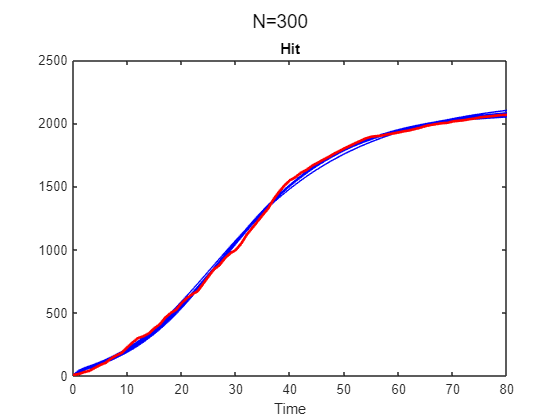

y7_2 = gsua_eval(T7.Estlsqc(:,1:end),T7,xdata,ydata2);

%savefig('iteration3/figures/curves.fig')

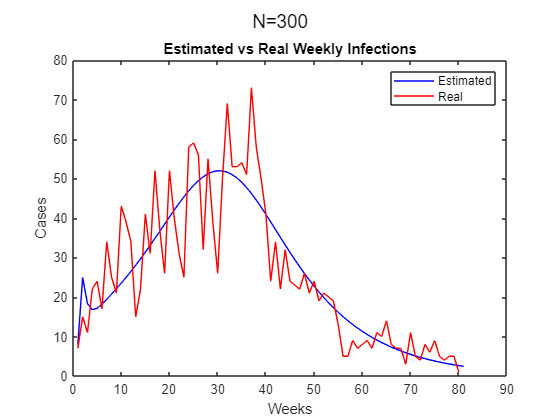

bestest_2 = y7_2(1,:);
trend = [bestest_2(1),bestest_2(2:end)-bestest_2(1:end-1)];
plot(trend,'b')
hold on
plot(diff(ydata2),'r')
title('Estimated vs Real Weekly Infections')
xlabel('Weeks')
ylabel('Cases')
legend({'Estimated','Real'})

%savefig('iteration3/figures1/EstimatedvsReal.fig')

T7.Nominal = T7.Estlsqc(:,1);

th_2 = 36

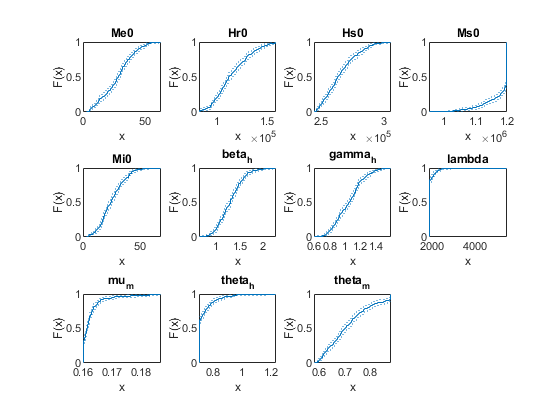

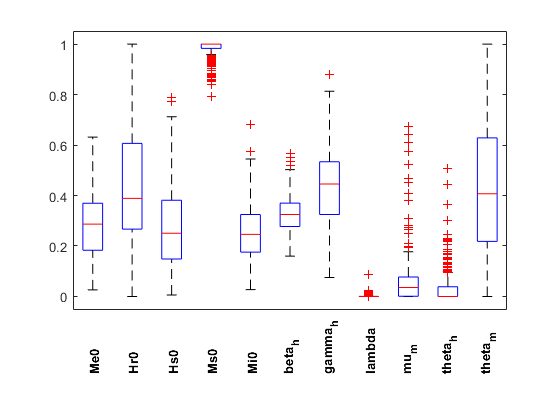

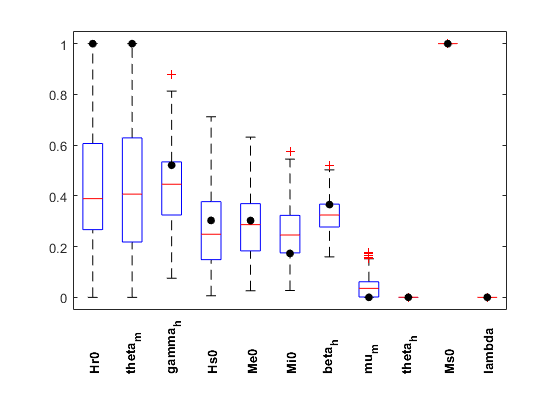

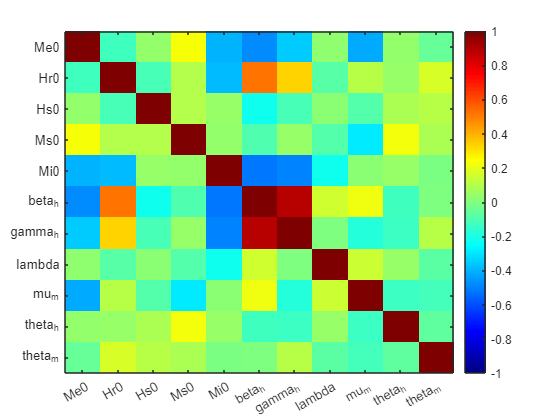

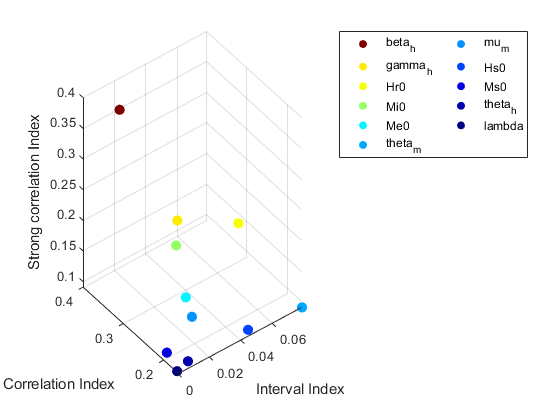

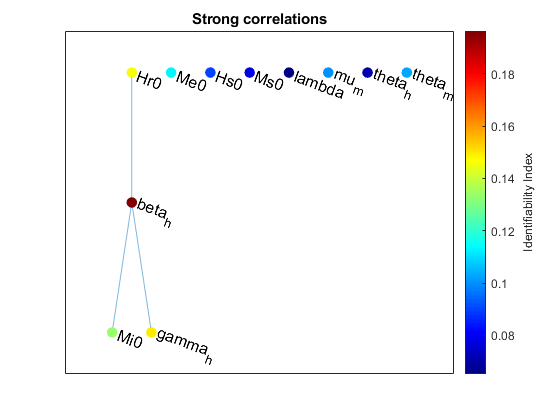

T = 11×5 table
                        Range               Nominal        Estlsqc           Est          index  
               ________________________    __________    ____________    ____________    ________

    Me0            26.827        30.507        28.667    1×300 double    1×300 double     0.11298
    Hr0        1.0895e+05    1.1406e+05    1.1151e+05    1×300 double    1×300 double       0.146
    Hs0        2.6192e+05    2.6559e+05    2.6376e+05    1×300 double    1×300 double    0.089983
    Ms0        1.1941e+06       1.2e+06       1.2e+06    1×300 double    1×300 double    0.077631
    Mi0            23.048         26.17        24.609    1×300 double    1×300 double     0.13347
    beta_h         1.2612 


T7_2ia = gsua_ia(T7,T7.Estlsqc(:,1:th_2), false, true); 

%savefig('iteration3/figures/Correlations.fig')

6. Análisis de incertidumbre

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 14:43:43
Number of simulations: 100


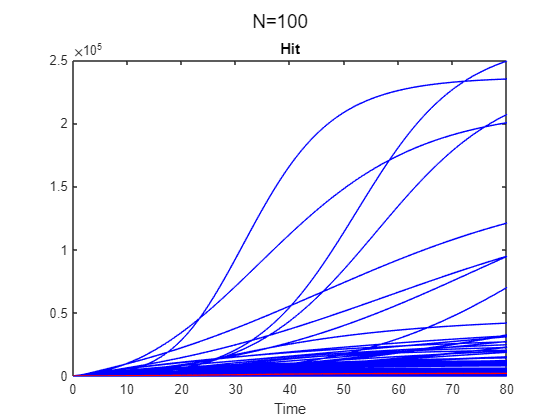

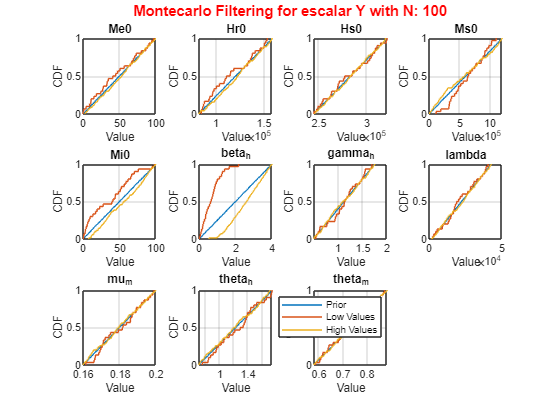


gsua_ua(M, T7, 'parallel', false, 'ynom',ydata2);

%savefig('iteration3/figures/Montecarlo.fig


## Cuarta Iteracion

Fijamos beta_m

NewRange(9,:) = 1.4622;

[T,~]=gsua_dpmat(odes,vars,[0 80],'7m','output',1,'opt',opts,'Range',NewRange);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T.Properties.CustomProperties.output = 1;
M = gsua_dmatrix(T,100);
T

T = 10×2 table
                        Range              Nominal  
               _______________________    __________

    Me0                0           100            50
    Hr0            81405    1.5881e+05    1.2011e+05
    Hs0        2.444e+05    3.2173e+05    2.8307e+05
    Ms0                0       1.2e+06         6e+05
    Mi0                0           100            50
    gamma_h          0.5          1.75         1.125
    lambda          1881         42694         22288
    mu_m            0.16           0.2          0.18
    theta_h          0.7          1.75         1.225
    theta_m         0.58          0.88          0.73


4. Estimamos los parámetros

opt = optimoptions('lsqcurvefit','UseParallel',true,'Display','iter');
[T7,res] = gsua_pe(T,xdata,ydata2,'N',100,'opt',opt); 
%save('iteration3/values/Results7.mat','T7_2','res_2','xdata','ydata2')

5. Análisis de identificabilidad

th_3 = sum(res<res(1)*1.8)

th_3 = 296

Sim296 Done
Sim295 Done
Sim294 Done
Sim293 Done
Sim292 Done
Sim291 Done
Sim290 Done
Sim289 Done
Sim288 Done
Sim287 Done
Sim286 Done
Sim285 Done
Sim284 Done
Sim283 Done
Sim282 Done
Sim281 Done
Sim280 Done
Sim279 Done
Sim278 Done
Sim277 Done
Sim276 Done
Sim275 Done
Sim274 Done
Sim273 Done
Sim272 Done
Sim271 Done
Sim270 Done
Sim269 Done
Sim268 Done
Sim267 Done
Sim266 Done
Sim265 Done
Sim264 Done
Sim263 Done
Sim262 Done
Sim261 Done
Sim260 Done
Sim259 Done
Sim258 Done
Sim257 Done
Sim256 Done
Sim255 Done
Sim254 Done
Sim253 Done
Sim252 Done
Sim251 Done
Sim250 Done
Sim249 Done
Sim248 Done
Sim247 Done
Sim246 Done
Sim245 Done
Sim244 Done
Sim243 Done
Sim242 Done
Sim241 Done
Sim240 Done
Sim239 Done
Sim238 Done
Sim237 Done
Sim236 Done
Sim235 Done
Sim234 Done
Sim233 Done
Sim232 Done
Sim231 Done
Sim230 Done
Sim229 Done
Sim228 Done
Sim227 Done
Sim226 Done
Sim225 Done
Sim224 Done
Sim223 Done
Sim222 Done
Sim221 Done
Sim220 Done
Sim219 Done
Sim218 Done
Sim217 Done
Sim216 Done
Sim215 Done
Sim214 Done
Sim2

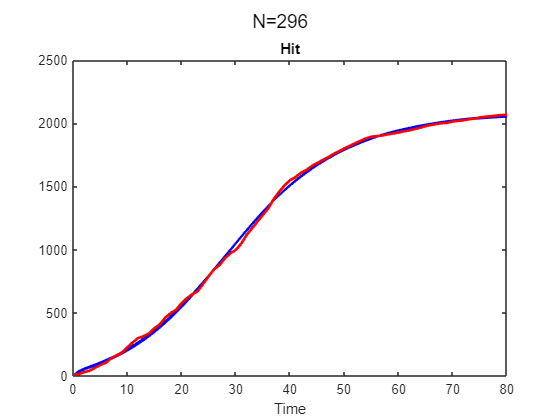

y7_3 = gsua_eval(T7.Estlsqc(:,1:th_3),T7,xdata,ydata2);

%savefig('iteration3/figures/curves.fig')

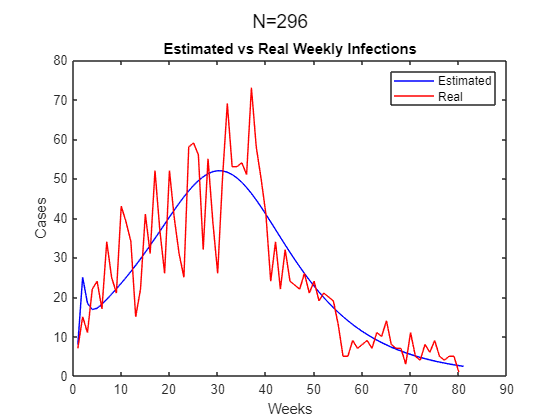

bestest_3 = y7_3(1,:);
trend = [bestest_3(1),bestest_3(2:end)-bestest_3(1:end-1)];
plot(trend,'b')
hold on
plot(diff(ydata2),'r')
title('Estimated vs Real Weekly Infections')
xlabel('Weeks')
ylabel('Cases')
legend({'Estimated','Real'})

%savefig('iteration3/figures1/EstimatedvsReal.fig')

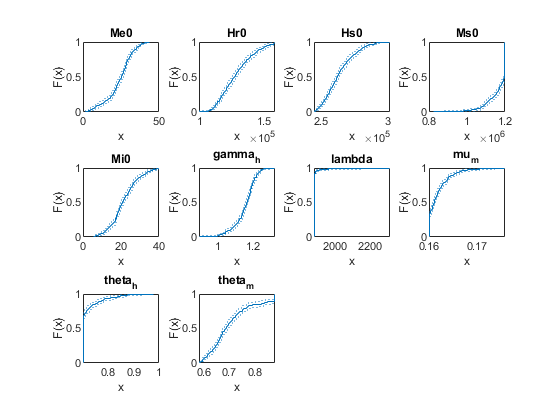

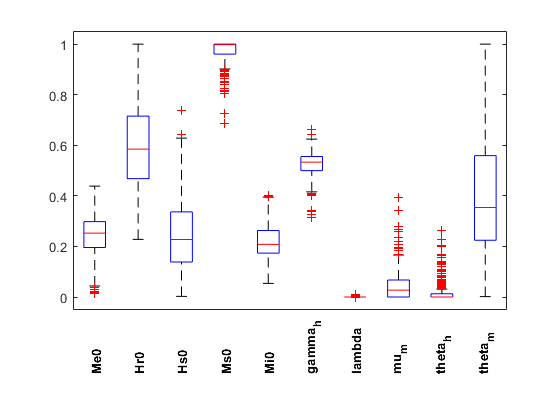

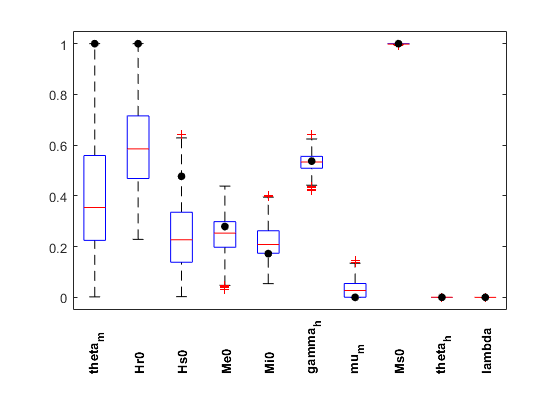

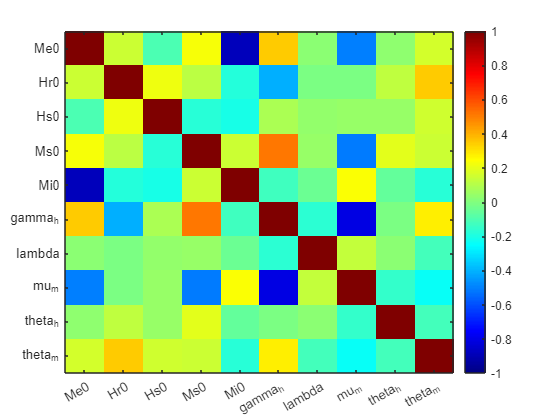

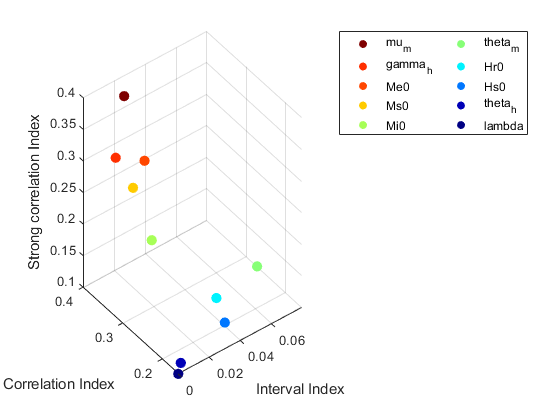

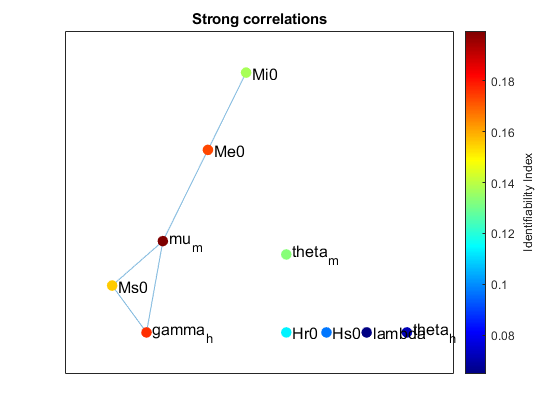

T = 10×5 table
                        Range               Nominal        Estlsqc           Est          index  
               ________________________    __________    ____________    ____________    ________

    Me0            24.043        26.532        25.288    1×300 double    1×296 double     0.17299
    Hr0        1.2479e+05    1.2859e+05    1.2669e+05    1×300 double    1×296 double     0.11347
    Hs0        2.6038e+05    2.6361e+05    2.6199e+05    1×300 double    1×296 double    0.097029
    Ms0        1.1901e+06       1.2e+06    1.1979e+06    1×300 double    1×296 double     0.15555
    Mi0            19.818        21.881        20.849    1×300 double    1×296 double     0.13704
    gamma_h        1.1577 

T7.Nominal = T7.Estlsqc(:,1);

T7_3ia = gsua_ia(T7,T7.Estlsqc(:,1:th_3), false, true); 

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 15:17:33
Number of simulations: 100


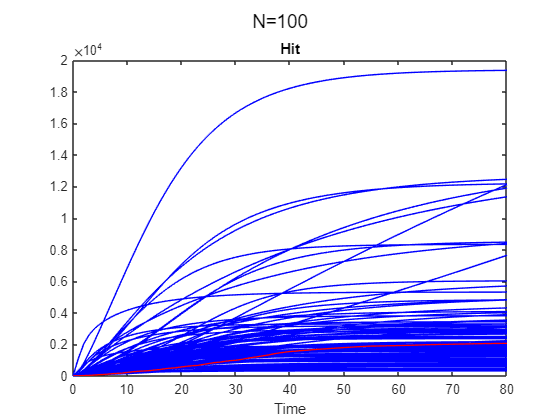

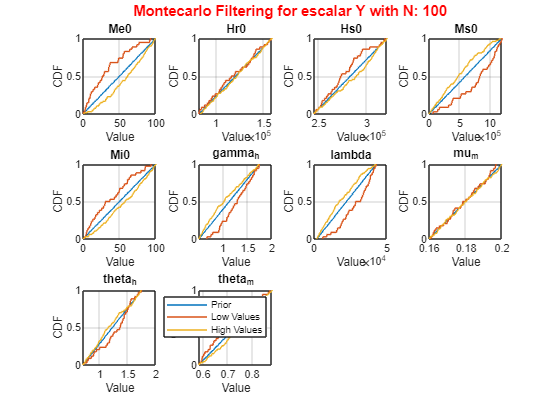

gsua_ua(M, T7, 'parallel', false, 'ynom',ydata2);

## **Quinta Iteracion**

Se noto en la iteracion anterior que mu_m esta muy correlacionado con otros dos parametros por lo que se procede a fijarlo.

mu_m esta pegado al intervalo inferior, por lo cual es posible que fijarlo en este valor disrrumpa los calculos. Considerar esto

NewRange(14,:) = 0.16;

[T,~]=gsua_dpmat(odes,vars,[0 80],'7m','output',1,'opt',opts,'Range',NewRange);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T.Properties.CustomProperties.output = 1;
M = gsua_dmatrix(T,100);
T

T = 9×2 table
                        Range              Nominal  
               _______________________    __________

    Me0                0           100            50
    Hr0            81405    1.5881e+05    1.2011e+05
    Hs0        2.444e+05    3.2173e+05    2.8307e+05
    Ms0                0       1.2e+06         6e+05
    Mi0                0           100            50
    gamma_h          0.5          1.75         1.125
    lambda          1881         42694         22288
    theta_h          0.7          1.75         1.225
    theta_m         0.58          0.88          0.73


4. Estimamos los parámetros

opt = optimoptions('lsqcurvefit','UseParallel',true,'Display','iter');
[T7,res] = gsua_pe(T,xdata,ydata2,'N',300,'opt',opt); 
%save('iteration3/values/Results7.mat','T7_2','res_2','xdata','ydata2')

5. Análisis de identificabilidad

th_4 = sum(res<res(1)*1.8)

th_4 = 300

Sim300 Done
Sim299 Done
Sim298 Done
Sim297 Done
Sim296 Done
Sim295 Done
Sim294 Done
Sim293 Done
Sim292 Done
Sim291 Done
Sim290 Done
Sim289 Done
Sim288 Done
Sim287 Done
Sim286 Done
Sim285 Done
Sim284 Done
Sim283 Done
Sim282 Done
Sim281 Done
Sim280 Done
Sim279 Done
Sim278 Done
Sim277 Done
Sim276 Done
Sim275 Done
Sim274 Done
Sim273 Done
Sim272 Done
Sim271 Done
Sim270 Done
Sim269 Done
Sim268 Done
Sim267 Done
Sim266 Done
Sim265 Done
Sim264 Done
Sim263 Done
Sim262 Done
Sim261 Done
Sim260 Done
Sim259 Done
Sim258 Done
Sim257 Done
Sim256 Done
Sim255 Done
Sim254 Done
Sim253 Done
Sim252 Done
Sim251 Done
Sim250 Done
Sim249 Done
Sim248 Done
Sim247 Done
Sim246 Done
Sim245 Done
Sim244 Done
Sim243 Done
Sim242 Done
Sim241 Done
Sim240 Done
Sim239 Done
Sim238 Done
Sim237 Done
Sim236 Done
Sim235 Done
Sim234 Done
Sim233 Done
Sim232 Done
Sim231 Done
Sim230 Done
Sim229 Done
Sim228 Done
Sim227 Done
Sim226 Done
Sim225 Done
Sim224 Done
Sim223 Done
Sim222 Done
Sim221 Done
Sim220 Done
Sim219 Done
Sim218 Done
Sim2

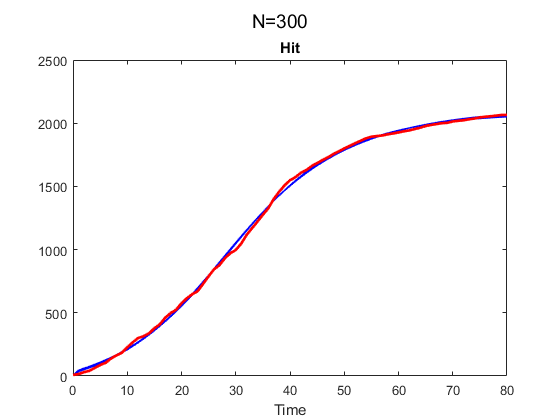

y7_4 = gsua_eval(T7.Estlsqc(:,1:end),T7,xdata,ydata2);

%savefig('iteration3/figures/curves.fig')

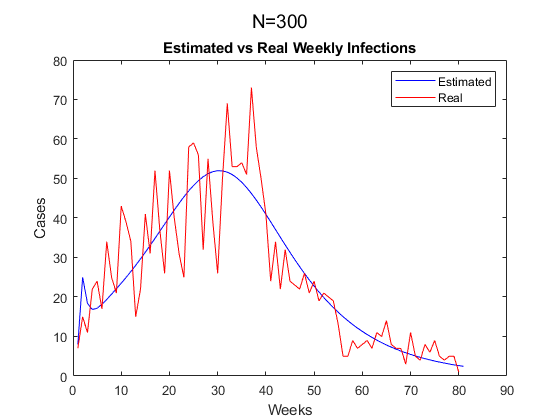

bestest_4  = y7_4(1,:);
trend = [bestest_4(1),bestest_4(2:end)-bestest_4(1:end-1)];
plot(trend,'b')
hold on
plot(diff(ydata2),'r')
title('Estimated vs Real Weekly Infections')
xlabel('Weeks')
ylabel('Cases')
legend({'Estimated','Real'})

%savefig('iteration3/figures1/EstimatedvsReal.fig')

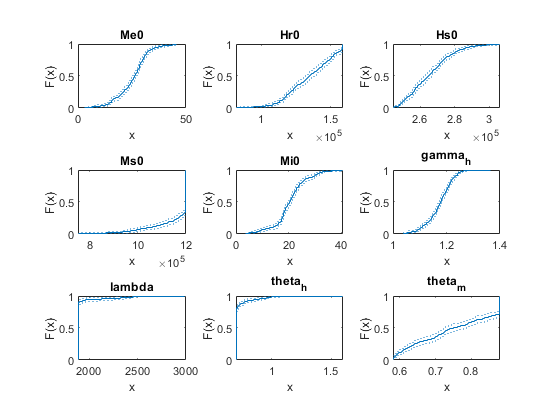

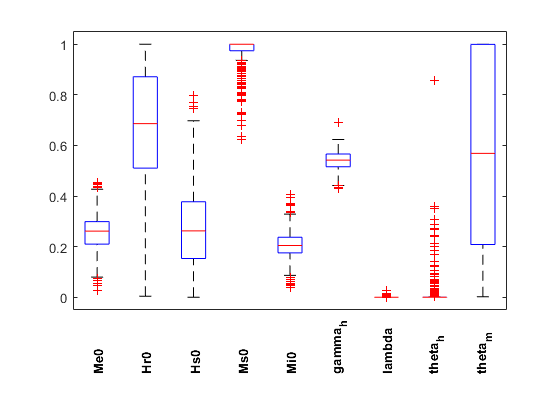

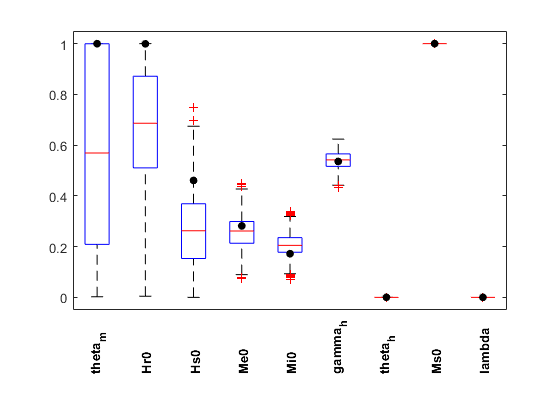

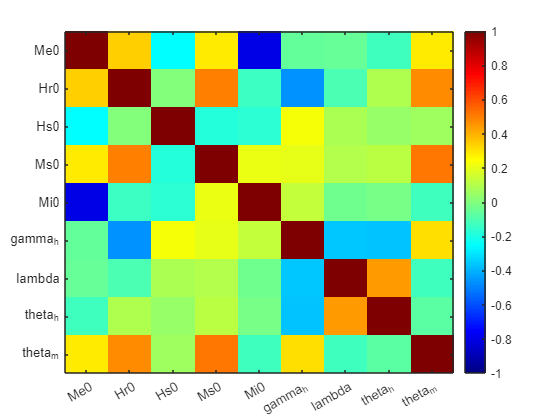

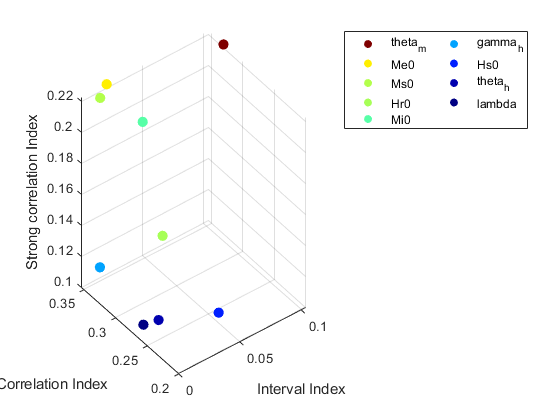

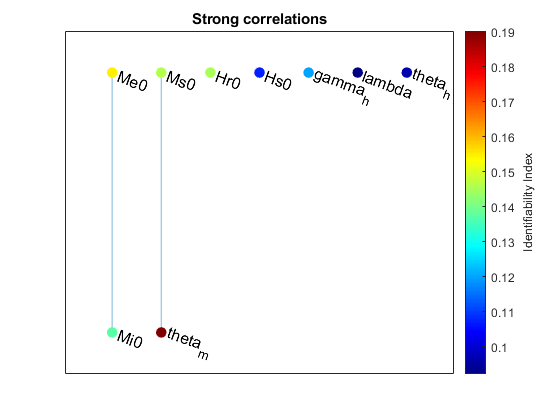

T = 9×5 table
                        Range               Nominal        Estlsqc           Est          index  
               ________________________    __________    ____________    ____________    ________

    Me0            25.097        27.188        26.142    1×300 double    1×300 double     0.15466
    Hr0        1.3216e+05    1.3693e+05    1.3455e+05    1×300 double    1×300 double     0.14487
    Hs0        2.6293e+05    2.6649e+05    2.6471e+05    1×300 double    1×300 double     0.10731
    Ms0        1.1884e+06       1.2e+06       1.2e+06    1×300 double    1×300 double     0.14614
    Mi0            19.594        21.364        20.479    1×300 double    1×300 double     0.13722
    gamma_h        1.1704  

T7.Nominal = T7.Estlsqc(:,1);

T7_4ia = gsua_ia(T7,T7.Estlsqc(:,1:th_4), false, true); 

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 16:17:50
Number of simulations: 100


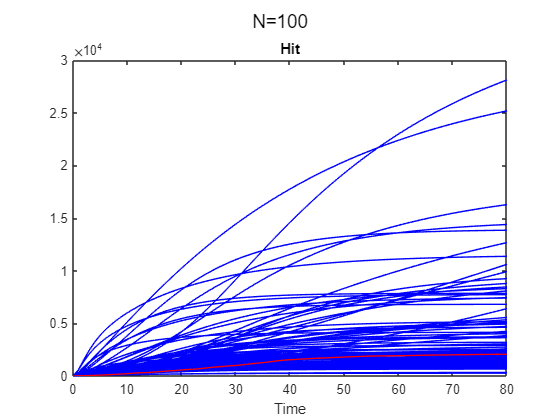

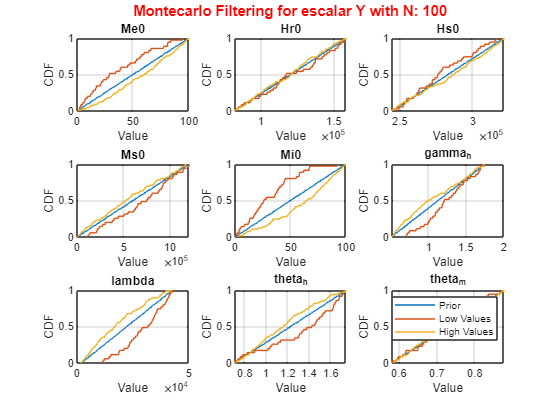

gsua_ua(M, T7, 'parallel', false, 'ynom',ydata2);

## Sexta Iteracion

NewRange(16,:) = 0.7506;

[T,~]=gsua_dpmat(odes,vars,[0 80],'7m','output',1,'opt',opts,'Range',NewRange);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T.Properties.CustomProperties.output = 1;
M = gsua_dmatrix(T,100);
T

T = 8×2 table
                        Range              Nominal  
               _______________________    __________

    Me0                0           100            50
    Hr0            81405    1.5881e+05    1.2011e+05
    Hs0        2.444e+05    3.2173e+05    2.8307e+05
    Ms0                0       1.2e+06         6e+05
    Mi0                0           100            50
    gamma_h          0.5          1.75         1.125
    lambda          1881         42694         22288
    theta_h          0.7          1.75         1.225


4. Estimamos los parámetros

opt = optimoptions('lsqcurvefit','UseParallel',true,'Display','iter');
[T7,res] = gsua_pe(T,xdata,ydata2,'N',300,'opt',opt); 

Generating a valid matrix for estimations
Estimation 1

                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9      8.7327e+06                      3.65e+06
     1         18     8.10594e+06             10       3.41e+06      
     2         27      7.6214e+06             20       6.49e+06      
     3         36     6.19658e+06             40       2.55e+06      
     4         45     3.98352e+06             80       6.67e+06      
     5         54      1.6152e+06        76.2818       1.53e+06      
     6         63     1.27423e+06        75.2852       3.54e+07      
     7         72          517885        16.6529       1.77e+06      
     8         81          485143        18.8213       5.22e+05      
     9         90          416761        37.6426       5.09e+06      
    10         99          339475        44.8869       2.75e+06      
    11        108          339475        50.998

%save('iteration3/values/Results7.mat','T7_2','res_2','xdata','ydata2')

5. Análisis de identificabilidad

th_4 = sum(res<res(1)*1.8)
y7_4 = gsua_eval(T7.Estlsqc(:,1:end),T7,xdata,ydata2);
%savefig('iteration3/figures/curves.fig')

bestest_4  = y7_4(1,:);
trend = [bestest_4(1),bestest_4(2:end)-bestest_4(1:end-1)];
plot(trend,'b')
hold on
plot(diff(ydata2),'r')
title('Estimated vs Real Weekly Infections')
xlabel('Weeks')
ylabel('Cases')
legend({'Estimated','Real'})
%savefig('iteration3/figures1/EstimatedvsReal.fig')

T7.Nominal = T7.Estlsqc(:,1);

T7_4ia = gsua_ia(T7,T7.Estlsqc(:,1:th_4), false, true); 

gsua_ua(M, T7, 'parallel', false, 'ynom',ydata2);